### This is a MATLAB live script for analyzing the first guesses of reponses to Guess the Number game

small interval: [1    10], n = 6

mid interval: [1    1,000], n = 30

big interval: [1    100,000], n = 4

MAX = 1000; % endpoint of interval
% This is the data for the first guess of participants who played the
% mid-sized interval ([1, 1000]) version of the "Guess the Number" game
data = [590, 500, 500, 800, 500, 69, 500, 22, 500, 56, 500, 100, 500, 200, 500, ...
    500, 500, 877, 700, 45, 500, 234, 239, 921, 500, 500, 500, 500, 529, 764]';
% create a logical vector of whether person knows bisection search
class = logical([1, 1, 1, 0, 1, 0, 0, 0, 1, 1, 1, 0, 1, 0, 1, 1, 1, ...
    0, 0, 1, 0, 0, 0, 0, 0, 0, 1, 1, 0, 1]); % 1 if participant knew Bisection Search
n = length(data)

n = 30

disp(["mean of first guess", num2str(mean(data))])

    "mean of first guess"    "454.8667"



disp(["standard deviation of first guess", num2str(std(data))])

    "standard deviation of first guess"    "240.2714"



gauss = makedist('Normal', 'mu', 500, 'sigma', std(data)); % N(mu=500, sigma=std), std estimated from data
unif = makedist('Uniform', "lower", 1, "upper", 1000); % Uniform(a=1, b=1000)

#### Analysis of complete data (both types of people)

binEdges = linspace(0,MAX,12)

binEdges = 	1.0e+03 *

         0    0.0909    0.1818    0.2727    0.3636    0.4545    0.5455    0.6364    0.7273    0.8182    0.9091    1.0000


hist = histogram(data, 'BinEdges', binEdges);
hold on
binCenters = binEdges(1:end-1) + diff(binEdges)/2

binCenters =    45.4545  136.3636  227.2727  318.1818  409.0909  500.0000  590.9091  681.8182  772.7273  863.6364  954.5455


obsCounts = hist.BinCounts % frequency 

obsCounts =      4     1     3     0     0    16     1     1     2     1     1


expCounts1 = round(n * diff(cdf(unif, [-inf binEdges(2:end-1) inf]))); % expected counts using Uniform distribution
expCounts2 = round(n * diff(cdf(gauss, [-inf binEdges(2:end-1) inf]))) % expected counts using Normal distribution

expCounts2 =      0     1     2     4     5     6     5     4     2     1     0


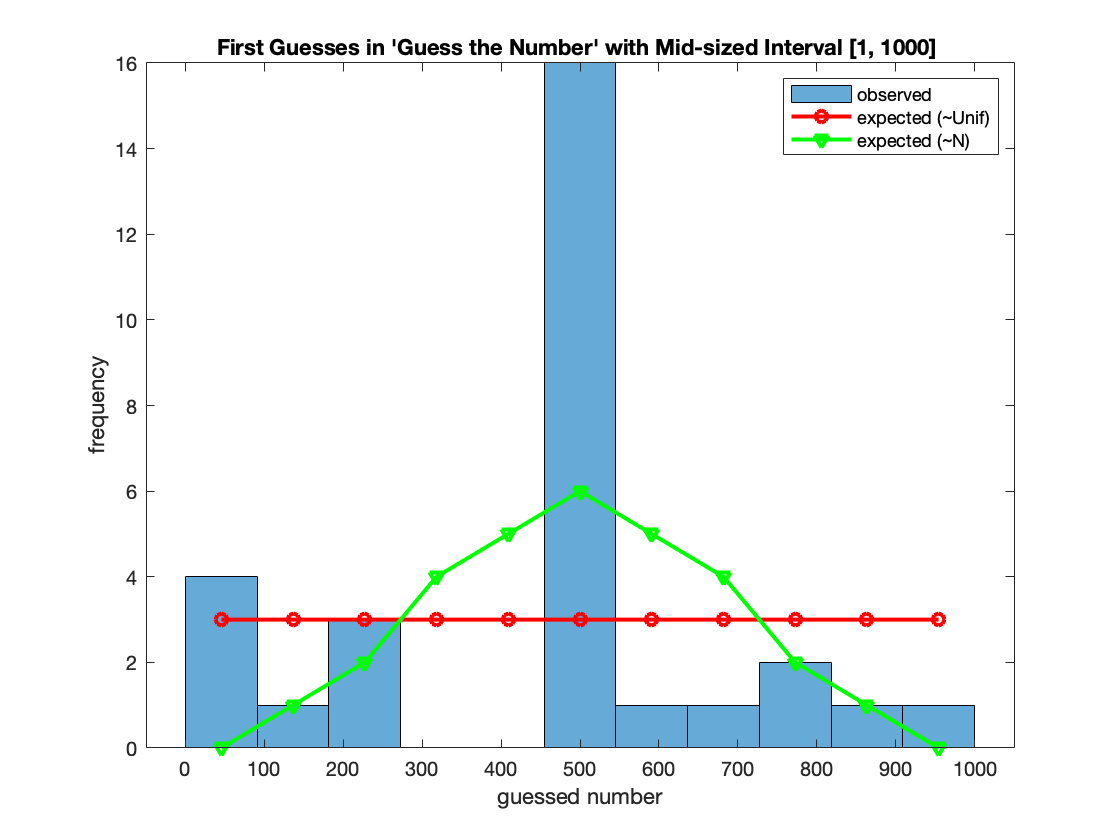

plot(binCenters, expCounts1,'LineWidth',2, 'Color', 'r', "Marker", "o")
plot(binCenters, expCounts2,'LineWidth',2, 'Color', 'g', "Marker", "v")
xlabel("guessed number"); ylabel("frequency"); 
title("First Guesses in 'Guess the Number' with Mid-sized Interval [1, 1000] ")
legend("observed", "expected (~Unif)", "expected (~N)")
hold off

% Perform Chi-Squared to test if the data is Gaussian with mean 500
[h,p,st] = chi2gof(data, 'CDF', gauss, 'NParams', 1) % nparams=1 because sigma estimated from data

h = 1

p = 1.2729e-05

st = struct with fields:
    chi2stat: 25.4009
          df: 3
       edges: [22.0000 381.6000 471.5000 561.4000 921.0000]
           O: [8 0 16 6]
           E: [7.7193 5.4110 5.8385 11.0311]


if h == 1
    disp("Chi-squared: The first guess is NOT Gaussian with mean 500")
else
    disp("Chi-squared: The first guess may be Gaussian with mean 500")
end

Chi-squared: The first guess is NOT Gaussian with mean 500


% Perform Chi-Squared to test if the data is Uniformly distributed
[h,p,st] = chi2gof(data, 'CDF', unif, 'NParams', 0) % no [araneters estimated for Uniform

h = 1

p = 0.0250

st = struct with fields:
    chi2stat: 5.0258
          df: 1
       edges: [22.0000 471.5000 921.0000]
           O: [8 22]
           E: [14.1291 15.8709]


if h == 1
    disp("Chi-squared: The first guess is NOT Uniformly distributed")
else
    disp("Chi-squared: The first guess may be Uniformly distributed")
end

Chi-squared: The first guess is NOT Uniformly distributed


#### Persons who knew Binary/Bisection Search 

% People who knew bisection search
hist = histogram(data(class), 'BinEdges', binEdges);
gauss.sigma = std(data(class)); % estimate standard deviation
hold on
obsCounts = hist.BinCounts % frequency 

obsCounts =      2     0     0     0     0    11     1     0     1     0     0


expCounts1 = round(n * diff(cdf(unif, [-inf binEdges(2:end-1) inf]))) % expected counts using Uniform distribution

expCounts1 =      3     3     3     3     3     3     3     3     3     3     3


expCounts2 = round(n * diff(cdf(gauss, [-inf binEdges(2:end-1) inf]))) % expected counts using Normal distribution

expCounts2 =      0     1     2     4     5     6     5     4     2     1     0


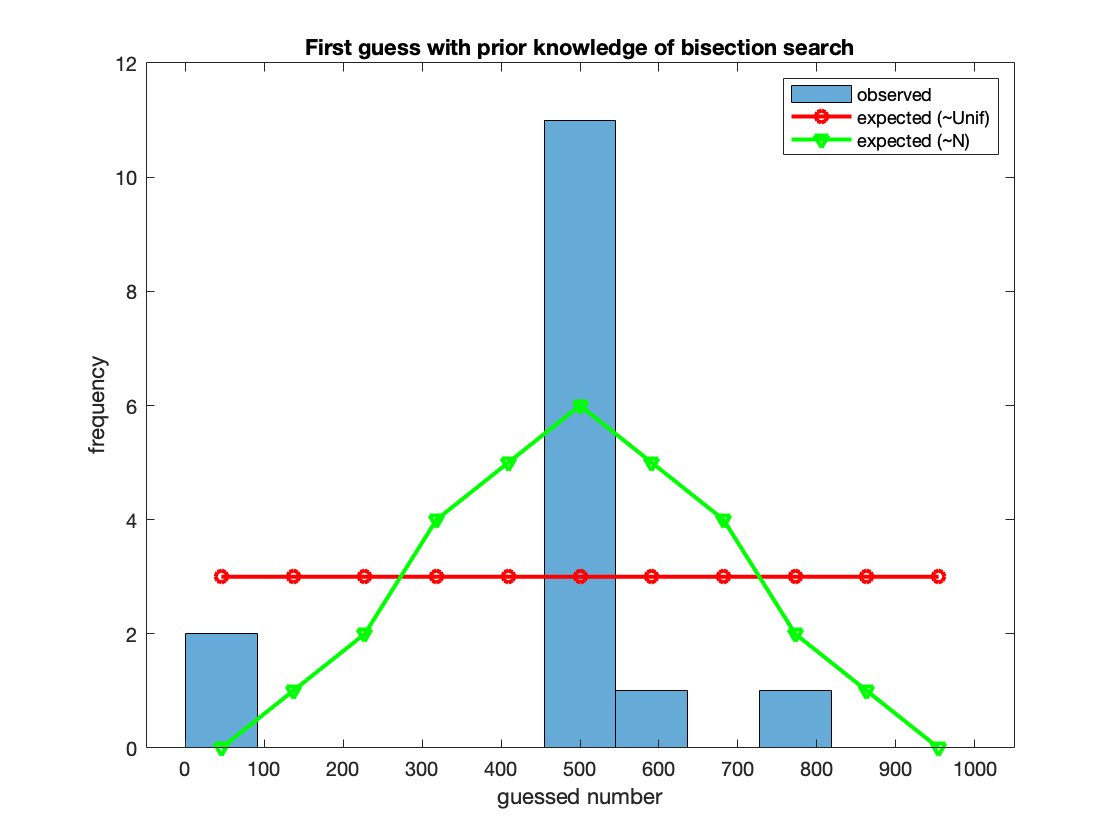

plot(binCenters, expCounts1,'LineWidth',2, 'Color', 'r', "Marker", "o")
plot(binCenters, expCounts2,'LineWidth',2, 'Color', 'g', "Marker", "v")
xlabel("guessed number"); ylabel("frequency"); 
title('First guess with prior knowledge of bisection search')
legend("observed", "expected (~Unif)", "expected (~N)")
hold off

% Perform Chi-Squared to test if the data is Gaussian with mean 500
[h,p,st] = chi2gof(data(class), 'CDF', gauss, 'NParams', 1) % nparams=1 because sigma estimated from data

h = 1

p = 0.0142

st = struct with fields:
    chi2stat: 6.0175
          df: 1
       edges: [45.0000 476.4000 764.0000]
           O: [2 13]
           E: [6.7249 8.2751]


if h == 1
    disp("Chi-squared: The first guess is NOT Gaussian with mean 500")
else
    disp("Chi-squared: The first guess may be Gaussian with mean 500")
end

Chi-squared: The first guess is NOT Gaussian with mean 500


% Perform Chi-Squared to test if the data is Uniformly distributed
[h,p,st] = chi2gof(data(class), 'CDF', unif, 'NParams', 0) % no [araneters estimated for Uniform

h = 1

p = 0.0079

st = struct with fields:
    chi2stat: 7.0566
          df: 1
       edges: [45.0000 476.4000 764.0000]
           O: [2 13]
           E: [7.1381 7.8619]


if h == 1
    disp("Chi-squared: The first guess is NOT Uniformly distributed")
else
    disp("Chi-squared: The first guess may be Uniformly distributed")
end

Chi-squared: The first guess is NOT Uniformly distributed


% Since Chi-square test rejected, model the first guess of people 
% who knew binary search as Bernoulli p(500) = 1-alpha, alpha << 0.5
p500 = sum(data(class)==500)/length(data(class))

p500 = 0.7333

% simulate data (pick 500 with P=p500, pick any other number with P=1-p500)


#### Persons who did NOT know Binary/Bisection Search 

% People who did not know bisection search
hist = histogram(data(~class), 'BinEdges', binEdges);
gauss.sigma = std(data(~class)); % estimate standard deviation
hold on
obsCounts = hist.BinCounts % frequency 

obsCounts =      2     1     3     0     0     5     0     1     1     1     1


expCounts1 = round(n * diff(cdf(unif, [-inf binEdges(2:end-1) inf]))) % expected counts using Uniform distribution

expCounts1 =      3     3     3     3     3     3     3     3     3     3     3


expCounts2 = round(n * diff(cdf(gauss, [-inf binEdges(2:end-1) inf]))) % expected counts using Normal distribution

expCounts2 =      2     2     2     3     4     4     4     3     2     2     2


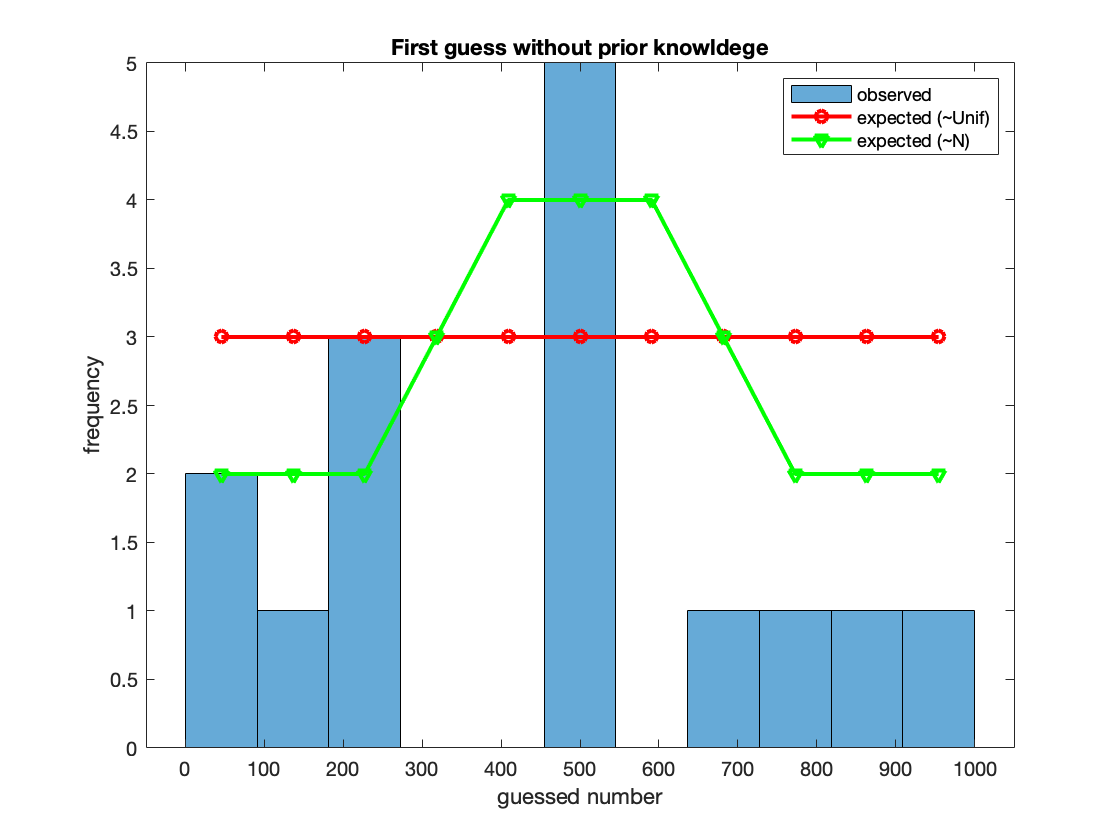

plot(binCenters, expCounts1,'LineWidth',2, 'Color', 'r', "Marker", "o")
plot(binCenters, expCounts2,'LineWidth',2, 'Color', 'g', "Marker", "v")
xlabel("guessed number"); ylabel("frequency"); 
title('First guess without prior knowldege')
legend("observed", "expected (~Unif)", "expected (~N)")
hold off

% Perform Chi-Squared to test if the data is Gaussian with mean 500
[h,p,st] = chi2gof(data(~class), 'CDF', gauss, 'NParams', 1) % nparams=1 because sigma estimated from data

h = 0

p = 0.6334

st = struct with fields:
    chi2stat: 0.2274
          df: 1
       edges: [22.0000 471.5000 921.0000]
           O: [6 9]
           E: [6.9207 8.0793]


if h == 1
    disp("Chi-squared: The first guess is NOT Gaussian with mean 500")
else
    disp("Chi-squared: The first guess may be Gaussian with mean 500")
end

Chi-squared: The first guess may be Gaussian with mean 500


% Perform Chi-Squared to test if the data is Uniformly distributed
[h,p,st] = chi2gof(data(~class), 'CDF', unif, 'NParams', 0) % no parameters estimated for Uniform

h = 0

p = 0.5819

st = struct with fields:
    chi2stat: 0.3032
          df: 1
       edges: [22.0000 471.5000 921.0000]
           O: [6 9]
           E: [7.0646 7.9354]


if h == 1
    disp("Chi-squared: The first guess is NOT Uniformly distributed")
else
    disp("Chi-squared: The first guess may be Uniformly distributed")
end

Chi-squared: The first guess may be Uniformly distributed
